Q-Learning algorithm

clear all
close all

Параметры для изучения

% NFFT = 512;             
% N_zero = Fs - NFFT;     % Кол-во нулей после вырезки. Я буде для частотного шага 1Гц
% N = floor(2/(NFFT/Fs)); % Количество вырезок за 2 секунды
% ds = 2;                 % В сколько раз уменьшить спектр. Минимум 2 - нормально

Функция вознаграждения

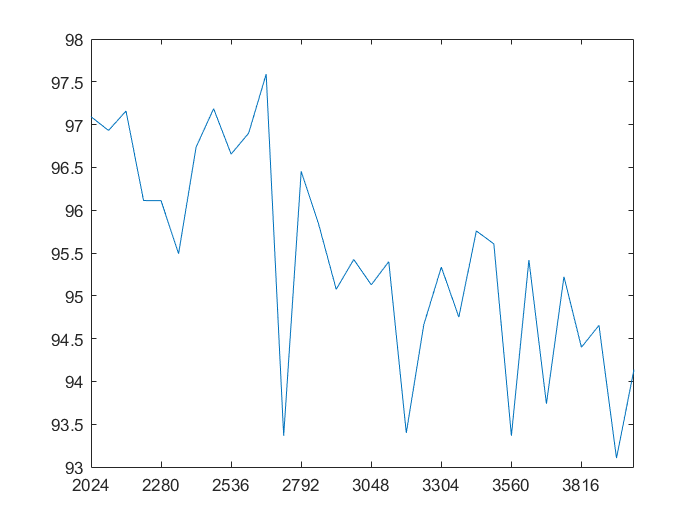

% tic
% x = ga(@GetReward, 1, [], [], [], [], 512, 4096)
% toc

% Input 0 -1    
% 1285 - максимум
var_nfft = [2024:64:4048];

for i = 1:length(var_nfft)
    x(i) = GetReward(var_nfft(i));
end

figure
plot(var_nfft, x)
xlim([min(var_nfft) max(var_nfft)])
xticks(min(var_nfft):256:max(var_nfft))

x = 1;
w = 0.5;    % 0.5030

bias = 512;
coef = 2048-512;% 0 - 1
learning_rate = 0.2;

for q = 1:2
    j = 1/(1+exp(-x * w));
    input = coef * j + bias;
    reward = GetReward(input);
    error = (100 - reward)/100;
    
    w = w + learning_rate *  (error * j) * (1 - j);
end

clear all
close all

var_nfft = floor([1:10] * 1024/10 + 1024);

for i = 1:length(var_nfft)
    x(i) = GetReward(var_nfft(i));
end

figure
plot(var_nfft, x(1:8))
xlim([min(var_nfft) max(var_nfft)])
xticks(min(var_nfft):512:max(var_nfft))

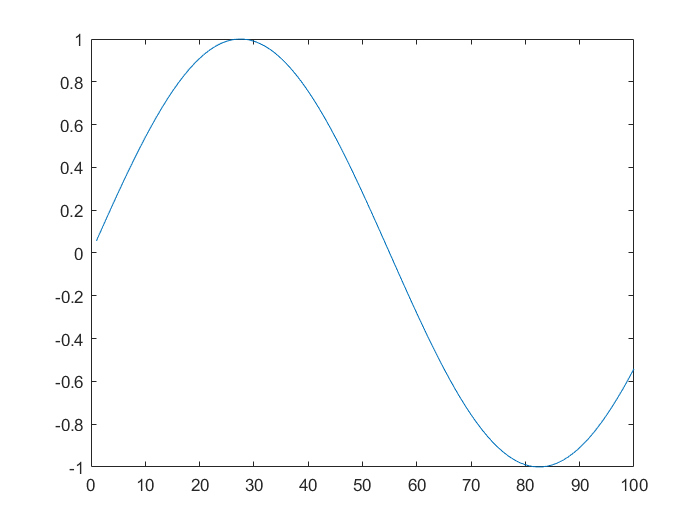

clear all
close all

t = 1:100;
s = sin(2*pi*t/110);

figure
plot(t,s)

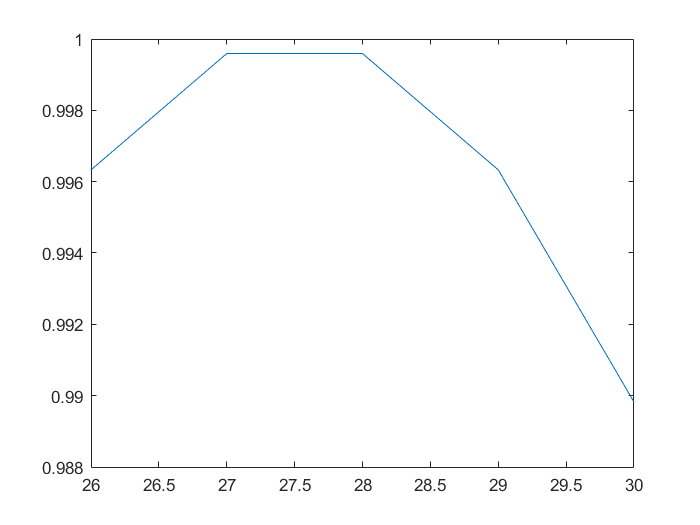


l = 0;
r = length(s);
EPS = 5;

while r - l > EPS 
   m1 = floor(l + (r - l) / 3); 
   m2 = floor(r - (r - l) / 3);
   
   if (s(m1) < s(m2))
      l = m1;
   else
      r = m2;
   end
   
end

figure
plot(t,s)
xlim([l r])

clear all
close all

EPS = 10;
l = 1250;
r = 1340;

while r - l > EPS 
   m1 = floor(l + (r - l) / 3); 
   m2 = floor(r - (r - l) / 3);
   
   f1 = GetReward(m1);
   f2 = GetReward(m2);
   
   if (f1 < f2)
      l = m1;
   else
      r = m2;
   end
   
end

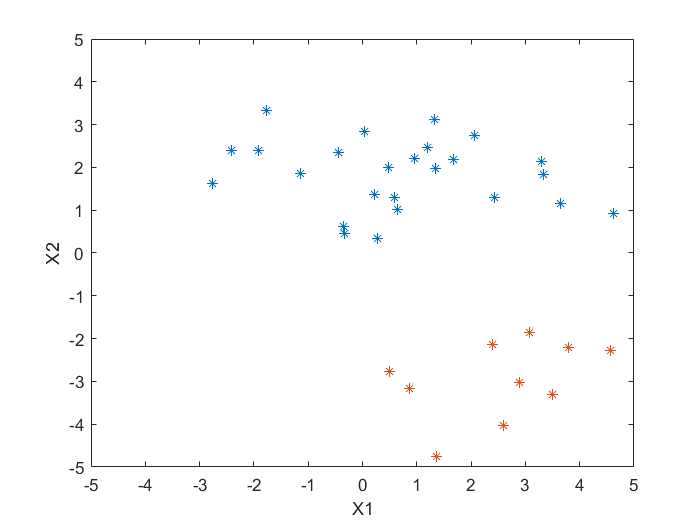

clear all
close all


x1 = normrnd(2,1,[1 25]);
y1 = normrnd(0.5,2,[1 25]);
figure
plot(y1, x1, '*')

x2 = normrnd(-3,1,[1 25]);
y2 = normrnd(5,3,[1 25]);
hold on
plot(y2, x2, '*')
xlabel('X1')
ylabel('X2')
xlim([-5 5])
ylim([-5 5])

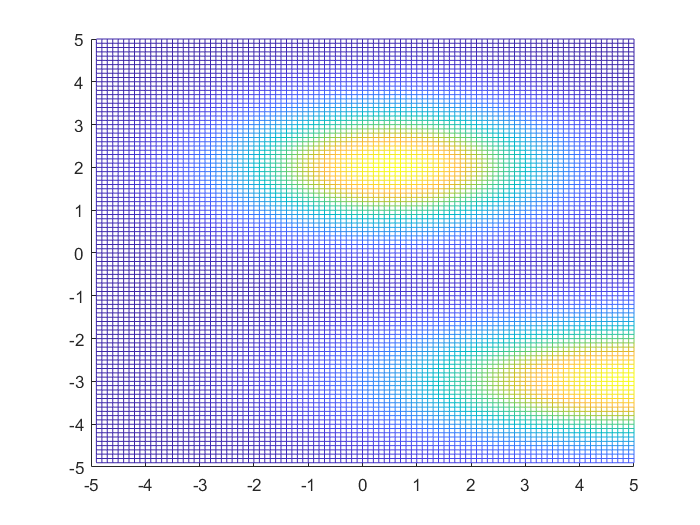


figure
t = ([1:100] - 50) / 10;
X1 = gaussmf(t, [1 -3])';
Y1 = gaussmf(t, [3 5]);
X2 = gaussmf(t, [1 2])';
Y2 = gaussmf(t, [2 0.5]);
z = X1*Y1 + X2*Y2;
plot(x1, y1, '*')
hold on
mesh(t, t, z);
xlim([-5 5])
ylim([-5 5])


% 
% x1 = 
% x2 = 
% X2 = 